# Shadowplot

This example shows how to use shadowplot, a very simple utility to add shadows to surface plots.

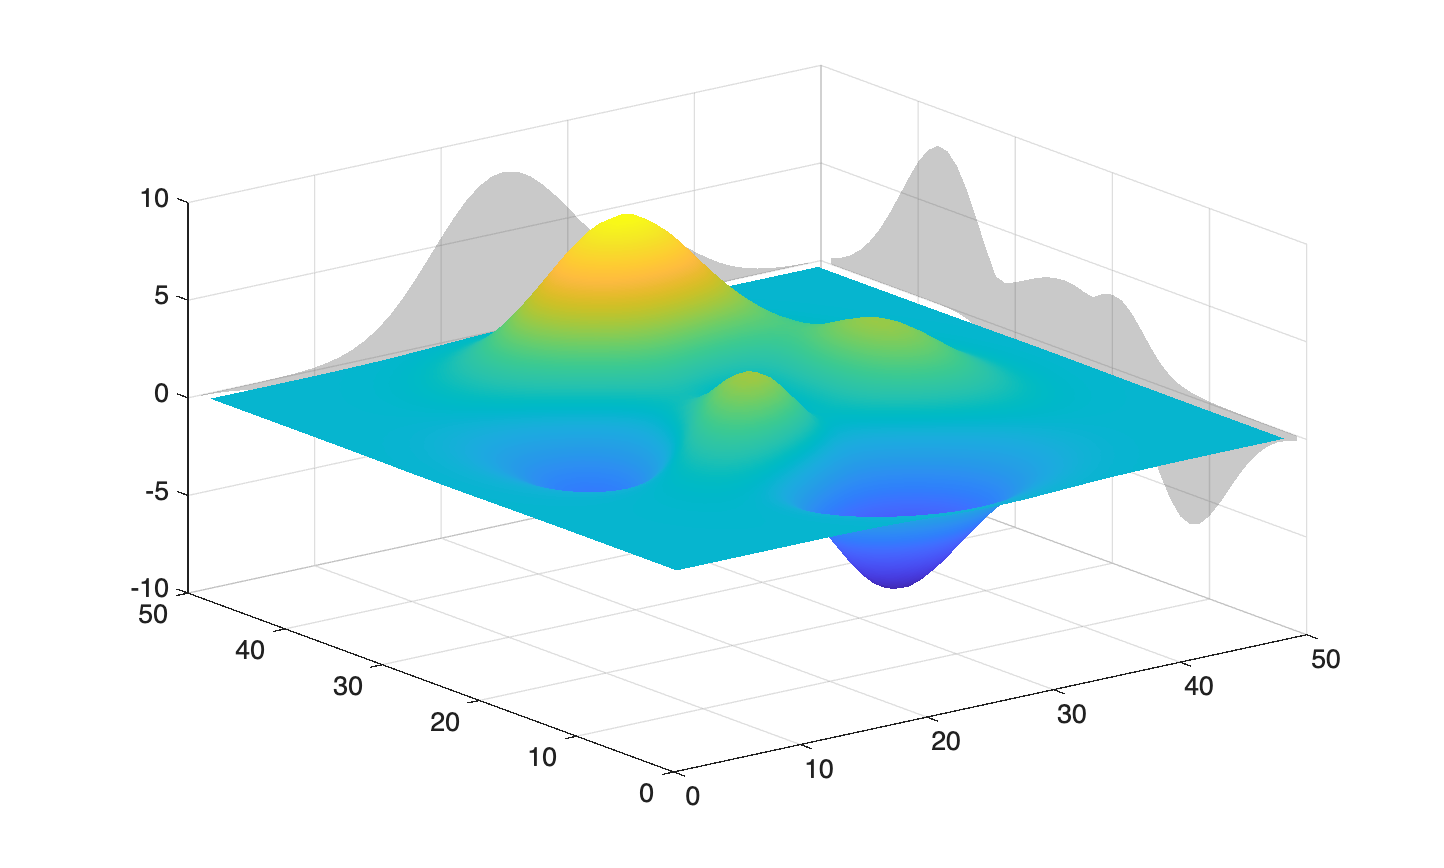

surf(peaks)
shading interp
shadowplot x   % Back X Wall
shadowplot y   % Back Y Wall

You can get a handle to the shadow to customize it. It's just a standard patch.

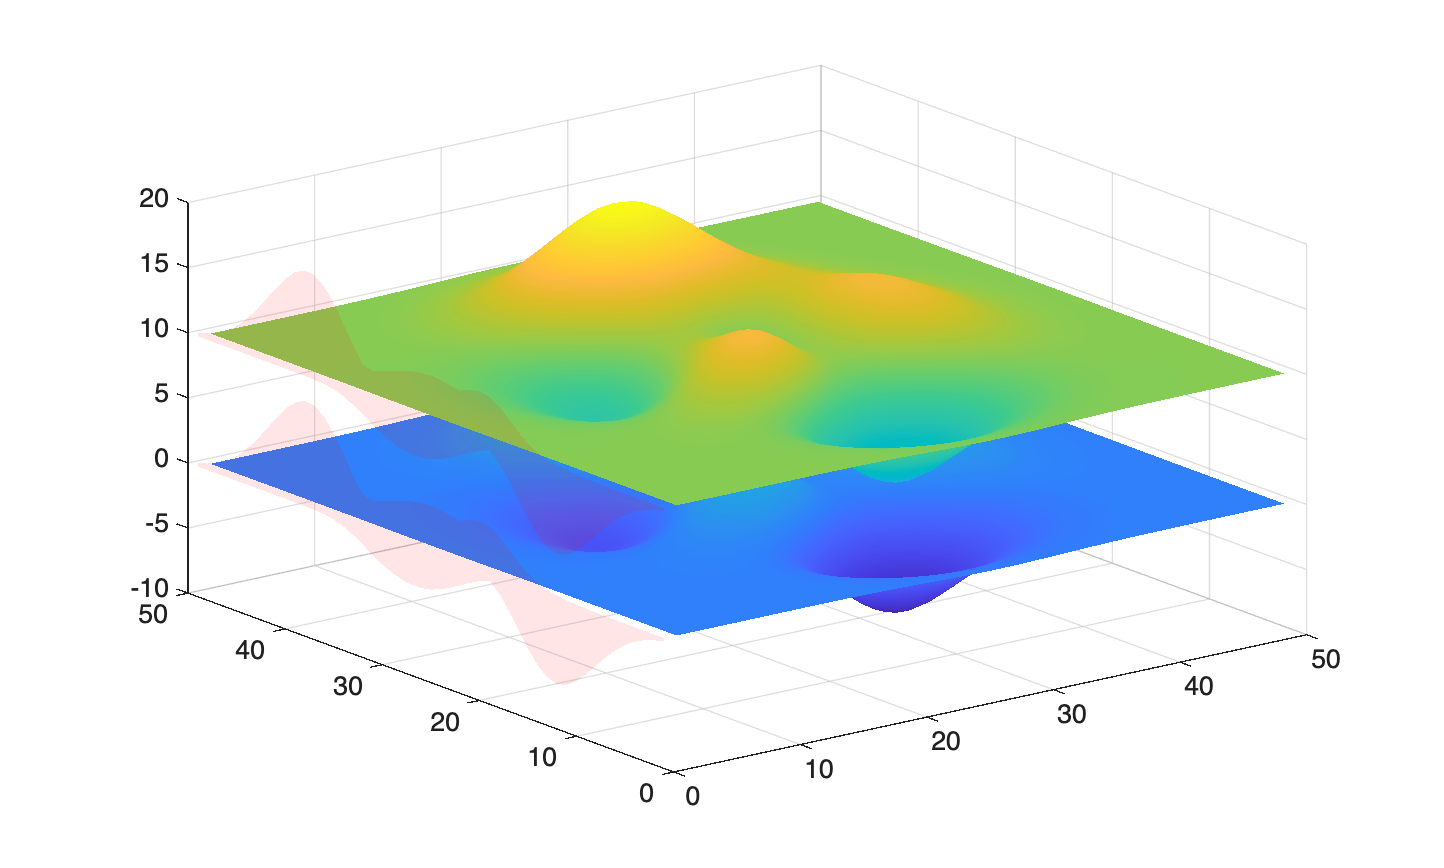

surf(peaks);hold on
surf(peaks+10)
shading interp
hs = shadowplot(1);
set(hs,'FaceColor','r');     % Red shadow
alpha(hs,.1)                 % More transparent
set(hs(1),'XData',get(hs(1),'XData')*.9)  % Move farther away